# F19 eksamen

## Opgave 1

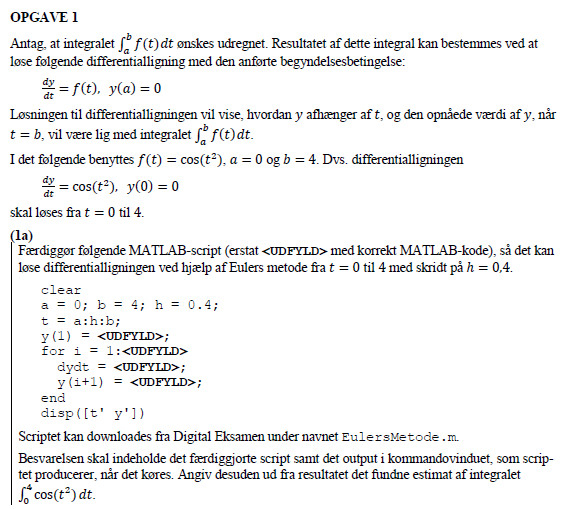

clear
a = 0; b = 4; h = 0.4;
t = a:h:b;

y(1) = 0;
for i = 1:b/h
  dydt = cos(t(i)^2);
  y(i+1) = y(i) + dydt*h;
end
disp([t' y'])

  Column 1

            0
          0.4
          0.8
          1.2
          1.6
            2
          2.4
          2.8
          3.2
          3.6
            4

  Column 2

            0
          0.4
      0.79489
       1.1157
       1.1679
      0.83366
      0.57221
       0.9187
      0.92429
      0.65001
       1.0194



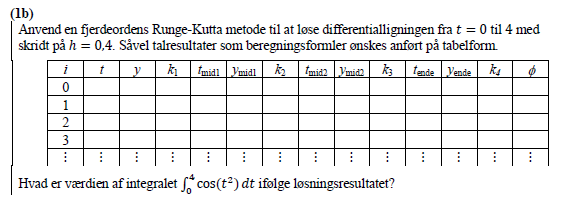

clear


t = [0, 4];
h = 0.4;
y0 = 0;

dYdt = @(t, Y) cos(t^2);

[t,Y, iter] = rk4system(dYdt, t, y0, h);


disp(table(iter, t, Y, 'VariableNames',{'Iteration', 'tid [s]', 'y'}))

    Iteration    tid [s]       y   
    _________    _______    _______

        0            0            0
        1          0.4      0.39894
        2          0.8       0.7678
        3          1.2      0.97404
        4          1.6      0.82585
        5            2      0.46119
        6          2.4       0.5093
        7          2.8       0.8049
        8          3.2      0.51715
        9          3.6      0.67565
       10            4      0.59385




int_res = Y(end)

int_res =       0.59385


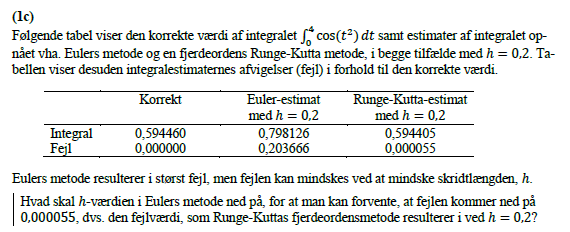

clear

h = 0.2;

fejl1 = 0.203666;

fejl2 = 0.000055;

h_ny = h * fejl2/fejl1

h_ny =      5.400999675940019e-05


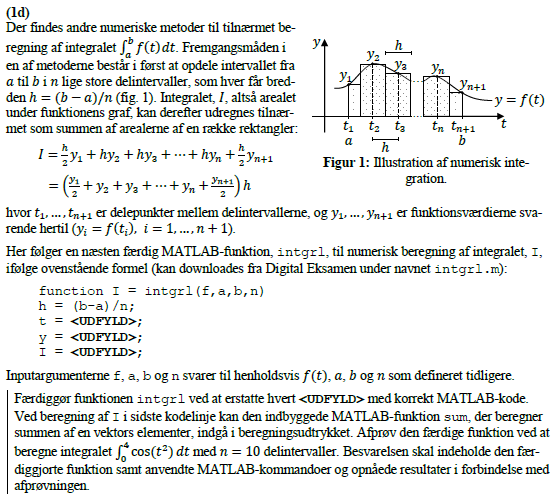

clear

a = 0; b = 4; h = 0.4;

n = 10;

f = @(t) cos(t.^2);

intgrl(f,a,b,10)

ans =    0.627885672876542


## Opgave 2

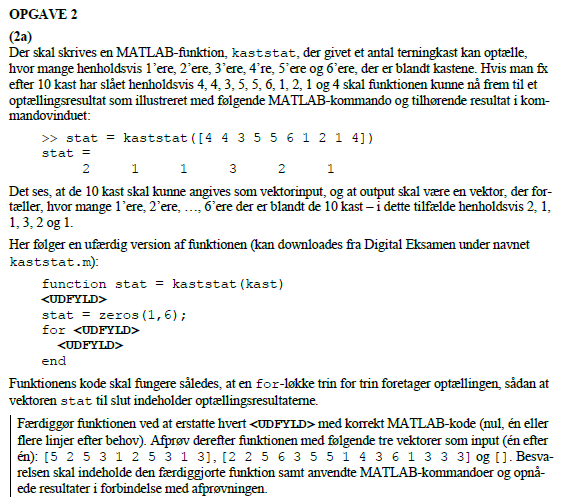

clear
kast1 = [5 2 5 3 1 2 5 3 1 3];

kaststat(kast1)

ans =      2     2     3     0     3     0



kast2 = [2 2 5 6 3 5 5 1 4 3 6 1 3 3 3];

kaststat(kast2)

ans =      2     2     5     1     3     2



kast3 = [];

kaststat(kast3)

ans =      0     0     0     0     0     0


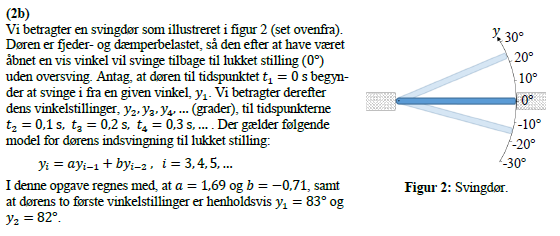

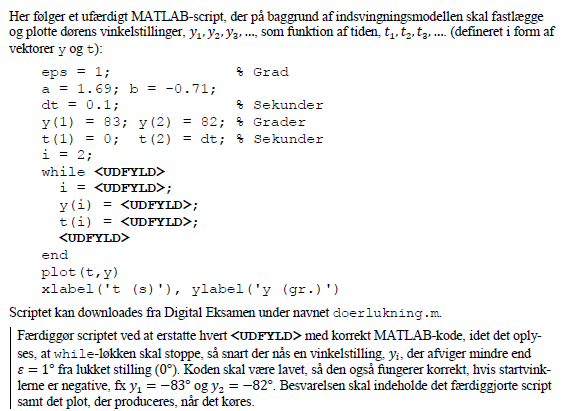

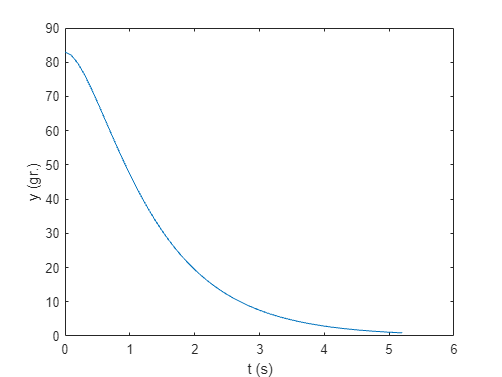

clear

eps = 1;              % Grad

a = 1.69; b = -0.71;

dt = 0.1;             % Sekunder

y(1) = 83; y(2) = 82; % Grader

t(1) = 0;  t(2) = dt; % Sekunder

i = 2;

while abs(y(i)) >= eps
  i = i + 1;
  y(i) = a*y(i-1) + b*y(i-2);
  t(i) = t(i-1) + dt;
end
plot(t,y)
xlabel('t (s)'), ylabel('y (gr.)')

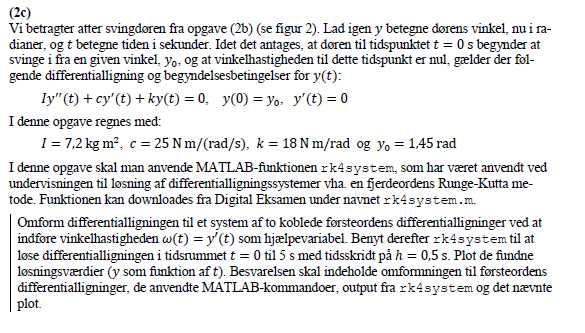

clear

I = 7.2; 
c = 25; 
k = 18; 
y0 = 1.45;

dYdt = @(t,Y) [Y(2), -(c*Y(2)+k*Y(1))/I];

tspan = [0 5]; 
Y0 = [y0 0]; 
h = 0.5;

[t,Y, iter] = rk4system(dYdt,tspan,Y0,h);

disp(table(iter, t, Y(:,1), Y(:,2)))

    iter     t            Var3                  Var4        
    ____    ___    __________________    ___________________

      0       0                  1.45                      0
      1     0.5      1.16888739189493     -0.729557820526388
      2       1     0.795445441058244     -0.666413349934818
      3     1.5     0.507111254161401     -0.471741919873312
      4       2     0.313855688628831     -0.305776543068676
      5     2.5     0.191468475848988     -0.190730046640499
      6       3     0.115962516214376     -0.116805055342708
      7     3.5    0.0699729010306759    -0.0708811750036438
      8       4    0.0421418452194937    -0.0428132993261806
      9     4.5    0.0253552831792228    -0.0257980712664684
     10       5    0.0152475841154066    -0.0155259663046698



## Opgave 3

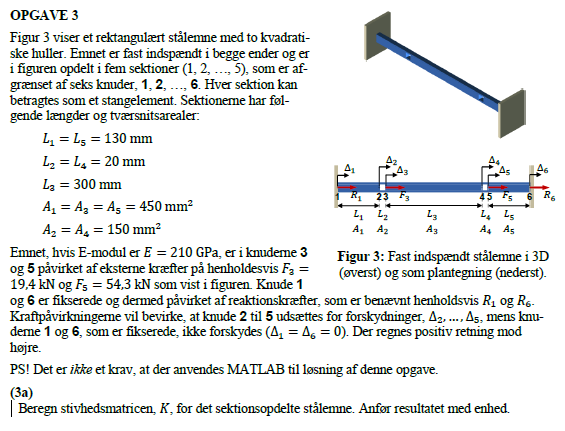

clear
format short

As = [450, 150, 450, 150, 450] * 1e-6;
Ls = [130, 20, 300, 20, 130] * 1e-3; 
E = 210e9; 


n = length(As);

K = zeros(n+1, n+1);
for j = 1:n
    k= As(j)*E/Ls(j);

    Kelm = [k, -k; -k, k];

    K(j:j+1,j:j+1) = K(j:j+1,j:j+1) + Kelm;

end

K 

K = 1.0e+09 *

    0.7269   -0.7269         0         0         0         0
   -0.7269    2.3019   -1.5750         0         0         0
         0   -1.5750    1.8900   -0.3150         0         0
         0         0   -0.3150    1.8900   -1.5750         0
         0         0         0   -1.5750    2.3019   -0.7269
         0         0         0         0   -0.7269    0.7269


Her er svaret i N/m, så den egentlige enhed her er GN/m

F3 = 19.4 * 1e3; % Newton
F5 = 54.3 * 1e3;


Pfri = [0 F3 0 F5]';    % Eksterne kræfter på de frie knuder (N)
Kfri = K(2:5, 2:5);          % Del af stivhedsmatrix svarende til frie knuder (N/m)
D = Kfri\Pfri;              % Forskydninger af de frie knuder (m)

% Kommer ud som meter
D_my = D'

D_my = 1.0e-04 *

    0.3351    0.4898    0.6473    0.6787



% Konvertering til mm
D = D_my * 1e3

D =     0.0335    0.0490    0.0647    0.0679


Det er forskydningerne som stangelement 2-5 oplever i milimeter

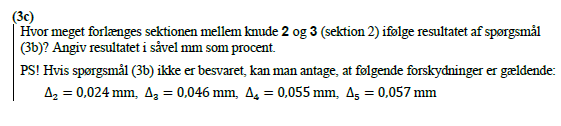

Dd = D(2) - D(1)

Dd = 0.0155


forl = Dd/Ls(2) * 100

forl = 77.3343

## Opgave 4

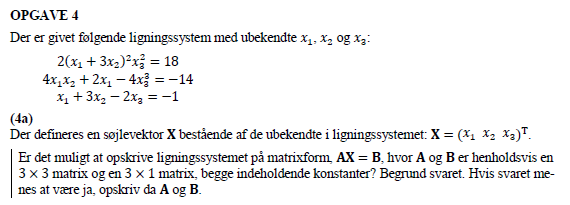

clear
syms x1 x2 x3

l1 = 2*(x1 + 3*x2)^2 * x3^2 - 18

$$l1 = 2\,{x_{3}}^{2}\,{\left(x_{1}+3\,x_{2}\right)}^{2}-18$$

l2 = 4*x1*x2 + 2*x1 - 4*x3^3 + 14

$$l2 = -4\,{x_{3}}^{3}+2\,x_{1}+4\,x_{1}\,x_{2}+14$$

l3 = x1 + 3*x2 - 2*x3

$$l3 = x_{1}+3\,x_{2}-2\,x_{3}$$


ls = [l1; l2; l3];
vars = [x1;x2;x3];

J = jacobian(ls, vars)

$$J = \left(\begin{array}{ccc} 2\,{x_{3}}^{2}\,\left(2\,x_{1}+6\,x_{2}\right) & 2\,{x_{3}}^{2}\,\left(6\,x_{1}+18\,x_{2}\right) & 4\,x_{3}\,{\left(x_{1}+3\,x_{2}\right)}^{2}\\ 4\,x_{2}+2 & 4\,x_{1} & -12\,{x_{3}}^{2}\\ 1 & 3 & -2 \end{array}\right)$$

dd =      2
     2
     2


ans = 3

Nej, det er ikke muligt, da det ses i jacobi matricen at de ubekendte indgår, hvilket gør ligningssystemet ulineært

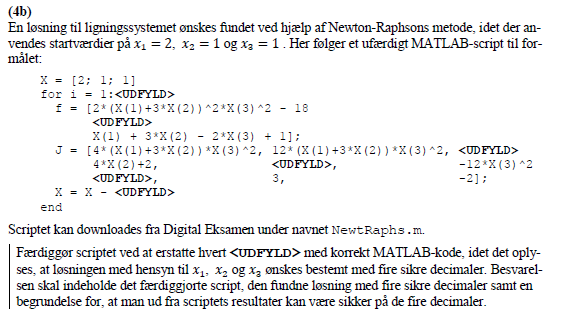

X = [2; 1; 1]

X =      2
     1
     1



for i = 1:5
  f = [2*(X(1)+3*X(2))^2*X(3)^2 - 18
       4*X(1)*X(2) + 2*X(1) - 4*X(3)^3 + 14
       X(1) + 3*X(2) - 2*X(3) + 1];

  J = [2*X(3)^2*(2*X(1) + 6*X(2)), 2*X(3)^2*(6*X(1) + 18*X(2)), 4*X(3)*(X(1) + 3*X(2))^2; 4*X(2) + 2, 4*X(1), -12*X(3)^2; 1, 3, -2];
  X = X - J\f
end

X =    -0.7143
    0.8000
    1.3429


X =    -0.0623
    0.7132
    1.5387


X =    -0.0991
    0.7009
    1.5018


X =    -0.1040
    0.7013
    1.5000


X =    -0.1040
    0.7013
    1.5000


# Funktioner

function [t,y,iter] = eulode(dydt,tspan,y0,h)
% eulode: Euler ODE solver
%   [t,y] = eulode(dydt,tspan,y0,h):
%           uses Euler's method to integrate an ODE
% input:
%   dydt = name of the M-file that evaluates the ODE
%   tspan = [ti, tf] where ti and tf = initial and
%   final values of independent variable
%   y0 = initial value of dependent variable
%   h = step size
% output:
%   t = vector of independent variable
%   y = vector of solution for dependent variable
if nargin<4,error('at least 4 input arguments required'),end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti),error('upper limit must be greater than lower'),end
t = (ti:h:tf)'; n = length(t);
% if necessary, add an additional value of t
% so that range goes from t = ti to tf
if t(n)<tf
    t(n+1) = tf;
    n = n+1;
end

end

function I = intgrl(f,a,b,n)
h = (b-a)/n;
t = a:h:b;
y = f(t);
I = h * (y(1)/2 + sum(y(2:n)) + y(n+1)/2);
end


function [t,Y, iter] = rk4system(dYdt,tspan,Y0,h)
% rk4system: Fourth order Runge-Kutta solver for a system
%            of ODEs
%   [t,Y] = rk4system(dYdt,tspan,Y0,h): uses a fourth 
%     order Runge-Kutta method to solve a system of
%     first order differential equations.
% input:
%   dYdt = a function of (t,Y), where t is the independent
%     variable (scalar) and Y is a row vector of the 
%     dependent variables. The function should return a
%     row vector of derivatives of the independent
%     variables as given by the differential equations.
%   tspan = [ti, tf] where ti and tf = initial and
%     final values of independent variable
%   Y0 = initial value of dependent variables (row
%     vector)
%   h = step size
% output:
%   t = vector with values of the independent variable
%   Y = matrix with solution values of the dependent
%     variables. Each column represents one dependent 
%     variable
ti = tspan(1);
tf = tspan(2);
t = (ti:h:tf)';
n = length(t);
Y(1,:) = Y0;

iter = [0,];
for i = 1:n-1
    iter(end+1) = i;
  k1 = dYdt(t(i),Y(i,:));
  tmid1 = t(i) + h/2;
  Ymid1 = Y(i,:) + k1*h/2;
  k2 = dYdt(tmid1,Ymid1);
  tmid2 = t(i) + h/2;
  Ymid2 = Y(i,:) + k2*h/2;
  k3 = dYdt(tmid2,Ymid2);
  tend = t(i) + h;
  Yend = Y(i,:) + k3*h;
  k4 = dYdt(tend,Yend);
  phi = (k1 + 2*k2 + 2*k3 + k4)/6;
  Y(i+1,:) = Y(i,:) + phi*h;
end
iter = iter';
end

function stat = kaststat(kast)

for i = 1:6
    stat(i) = sum(kast == i);
end

end


